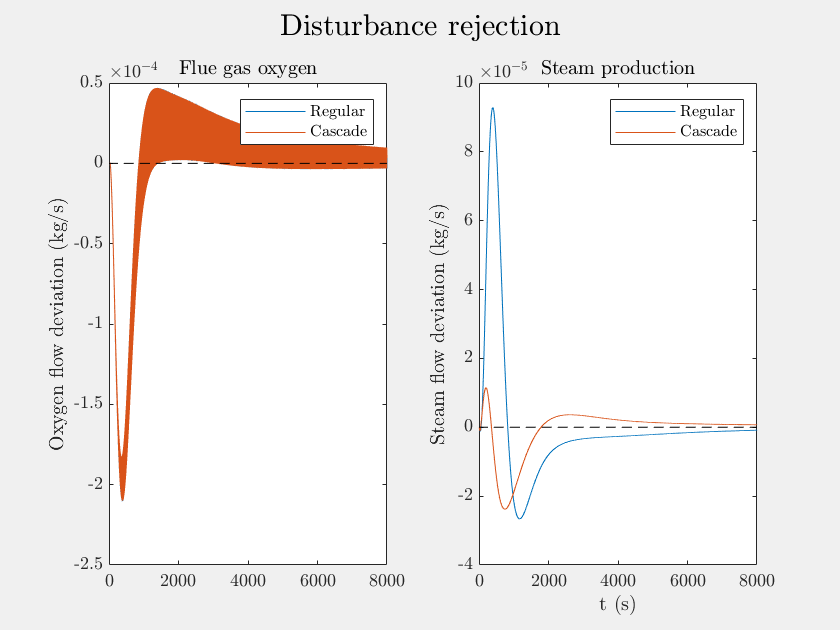

% Create and plot the disturbance response of the Furnace model.
%
% This live script assumes the following variables are defined in the workspace.
%
%   ss_state:   ModelOperatingPoint representing a steady state of the
%               system. Do
%                   >> ss_state = create_ss_state(12000);
%               to create it from scratch.
%
% If the MPC disturbance rejection is to be plotted, the MPC object lmpc must also
% be defined.

clf;
warning('off','all');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

FurnaceParameters;

%%% Begin configuration %%%

ss_time = 12000;                            % The time to simulate to finish startup and get a steady state.
settle_time = 4000;                         % The time to simulate with controller online to let it settle.
run_time = 8000;                            % The time to simulate with disturbance.
reset_all = false;                          % Clear all variables instead of loading from workspace.
controller_type_names = ["AB", "Cascade"];  % The controller types to evaluate. AB and Casade MUST be present
                                            % and at indices 1 and 2, respectively. After them, MPC
                                            % and Open are optional.
disturbance_factor = 0.1;                   % The  relative size of the waste disturbance.

F_st_process_max = 18.58;   % Max steam flow from process data.
F_st_process_min = 14.74;   % Min steam flow from process data.
F_st_process_sp = 16.5;     % Steam flow setpoint from process data.

% The following two variables have a chicken-and-the-egg problem. To know
% them, you must do a simulation.
% If you want to recalculate F_st_sim_open_dy, set it F_st_sim_open_dy = 1.0
% and do an open-loop disturbance simulation. Then set the variable equal
% to the resulting steady-state steam flow deviation ("overshoot").
% To recalculate F_st_sim_disturbance_acceptance, simply run an AB
% controller disturbance simulation and set it equal to the corresponding
% disturbance acceptance.
% When the variables have been recalculated, just run the live script (with
% reset_all = false) again to reanalyze energy production.
F_st_sim_open_dy = 1.0423;  % Open-loop steam flow deviation.
F_st_sim_disturbance_acceptance = 8.7920e-05; % AB controller disturbance rejection.

%%% End configuration %%%

if reset_all || ~(exist("orig_ss_state"))
    orig_ss_state = create_ss_state(12000);
end

% Iterate over all controller types to be evaluated and simulate them
% if they are not already simulated.
for i = 1:length(controller_type_names)
    controller_type_name = controller_type_names(i);
    
    if reset_all || ~(exist(sprintf("simOut_%s", controller_type_name)));
        ss_state = orig_ss_state;
        
        % Reset parameters and set all input types to controlled.
        FurnaceParameters;
        eval(sprintf("reg.controller_type = ControllerType.%s;", controller_type_name));
        reg.sp_F_st = reg.op_F_st;
        reg.F_w_pert_amp = 0;
        suffixes = ["F_aI" "F_aII" "F_w_in" "v_grate" "HHV" "AB"];
        for i = 1:length(suffixes)
            eval(sprintf("reg.input_type_%s = InputType.Controlled;", suffixes(i)));
        end
        
        % Let the controller settle
        settleSim = sim_from_ss(ss_state, settle_time);
        ss_state = settleSim.ss_state_out;
        
        % Apply disturbance and simulate
        reg.F_w_pert_amp = -1*reg.const_F_w_in*disturbance_factor; % Negative values here create large disturbances
        reg.F_w_pert_freq = 1/((ss_time + settle_time + run_time)*10);
        
        distSim = sim_from_ss(ss_state, run_time);
        
        % Save the result
        eval(sprintf("simOut_%s = distSim;", controller_type_name))
    end
end
    
% Load the simulations from workspace
stats = {};
sims = [];
for i = 1:length(controller_type_names)
    controller_type_name = controller_type_names(i);
    eval(sprintf("sims{end+1} = simOut_%s;", controller_type_name));
end

% Prepare figures
fig_cv = figure();
sgtitle("Disturbance rejection", "Interpreter", "Latex");
fig_mv = figure();
sgtitle("Input usage", "Interpreter", "Latex");

% Analyze simulations and plot their data.
uss = {};
tuss = {};
for n = 1:length(sims)
    controller_type_name = controller_type_names(n);
    
    % Extract response data
    curSim = sims{n};
    stats{n}.name = controller_type_name;
    
    ys = {};
    tys = {};
    [ys{1}, tys{1}, ~, ~] = load_data('O2', curSim);
    [ys{2}, tys{2}, us, tus] = load_data('st', curSim);
    sps = [reg.sp_F_O2 reg.sp_F_st];
    uss{n} = us;
    tuss{n} = tus;
    
    % Calculate performance
    stats{n}.iaes = [];
    stats{n}.overshoots = [];
    stats{n}.sses = [];
    stats{n}.max_input_usages = [];
    stats{n}.settling_times = [];
    stats{n}.disturbance_acceptance = [];
    stats{n}.rel_delta_power = [];
    
    figure(fig_cv);
    for i = 1:2
        
        subplot(1,2,i);
        if i == 1
            title("Flue gas oxygen", "Interpreter", "Latex");
            ylabel("Oxygen flow deviation (kg/s)", "Interpreter", "Latex")
        else
            title("Steam production", "Interpreter", "Latex");
            ylabel("Steam flow deviation (kg/s)", "Interpreter", "Latex")
            xlabel("t (s)", "Interpreter", "Latex");
        end
        
        sp = sps(i);
        y = ys{i};
        
        ty = tys{i};
        dty = ty - ty(1);
        
        plot(dty, y-y(1));
        hold on;
        
        % Integrated absolute error
        stats{n}.iaes(i) = trapz(dty, abs(y - sp));
        
        % Steady state error
        stats{n}.sses(i) = y(end) - sp;
        
        % Overshoot per disturbance
        overshoot = max(abs(y - sp));
        stats{n}.overshoots(i) = overshoot / (reg.const_F_w_in*disturbance_factor);
        
        % Settling time
        settling_idx = find(abs(y - sp) >= 0.05*(overshoot), 1, 'last');
        stats{n}.settling_times(i) = dty(settling_idx);
        
        % Relative disturbance acceptance
        disturbance_acceptance = overshoot / F_st_sim_open_dy;
        stats{n}.disturbance_acceptance(i) = disturbance_acceptance;
        
        % Increased power production because of setpoint increase
        F_st_sim_delta_sp = (1 - disturbance_acceptance / F_st_sim_disturbance_acceptance) * ...
            (F_st_process_max - F_st_process_sp);
        stats{n}.rel_delta_power(i) = F_st_sim_delta_sp / F_st_process_sp;

    end
    
    % Analyze input usage
    figure(fig_mv);
    for i = 1:4
        
        % Load input usage data from workspace
        u = us{i};          % Input usage
        tu = tus{i};        % Input usage time
        dtu = tu - tu(1);   % Relative input usage time
        
        % Save input usage stats
        stats{n}.max_input_usages(i) = max(abs(u - u(1)));
                
        % Don't bother plotting input usage for MPC and Open.
        if n >= 3
            continue;
        end
        
        subplot(2,2,i);
        hold on;
        mv_names = ["Sec. air", "Prim. air", "Grate speed", "Waste feed"];
        title(mv_names(i), "Interpreter", "Latex");
        xlabel("t (s)", "Interpreter", "Latex");
        
        
        % Since the AB and cascade controllers can produce very similar
        % input plots, we also want to show their difference explicitly. To
        % do this we must interpolate their input usage values and sample
        % to a common time scale to enable subtraction.
        
        % Load the AB input usage
        if n == 1 && controller_type_name ~= "AB"
            error("The AB controller must be the first in sims");
        end
        u_orig = uss{1}{i};
        tu_orig = tuss{1}{i};
        dtu_orig = tu_orig - tu_orig(1);
        
        % Interpolate and resample
        dtu_ipl = 1:0.1:8000;
        u_orig_ipl = interp1(dtu_orig, u_orig, dtu_ipl);
        u_ipl = interp1(dtu, u, dtu_ipl);
        
        % Plot the input usage
        plot(dtu_ipl, u_ipl-u_ipl(1));
        
        % Plot the input usage difference
        if n == 2 && controller_type_name ~= "Cascade"
            error("The cascade controller must be the second in sims");
        end
        if n == 2
            yyaxis right;
            plot(dtu_ipl, u_ipl-u_orig_ipl-(u_ipl(1)-u_orig_ipl(1)), '-');
            yyaxis left;
        end
        xlim([min(dtu) max(dtu)]);
    end
end

% Do some plot prettifying
figure(fig_cv);
set(gcf, 'Visible', 'on');
for n = 1:2
    subplot(1,2,n);
    legend('Regular', 'Cascade', 'Interpreter', 'Latex');
    plot(dty, repmat([0],1,length(dty)), 'k--','HandleVisibility','off');
end

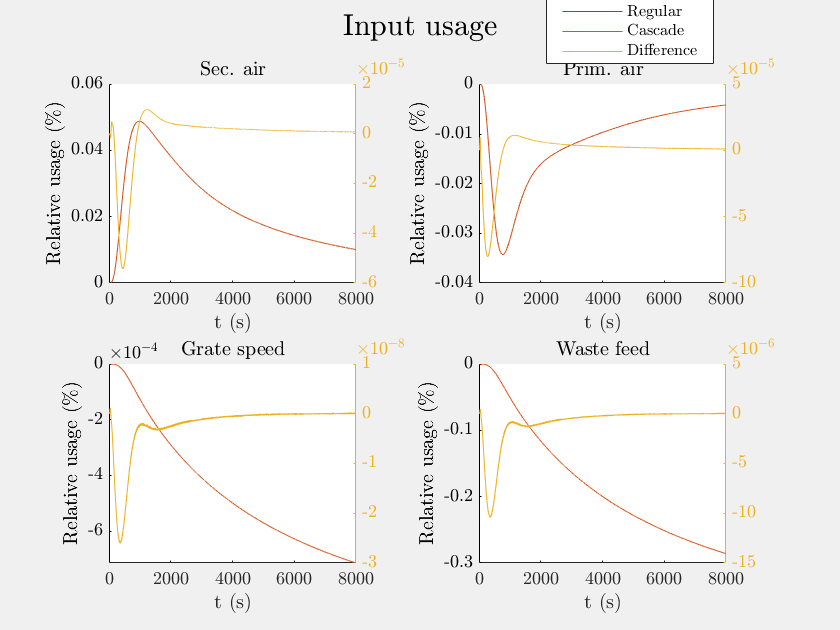


figure(fig_mv);
set(gcf, 'Visible', 'on');
for i = 1:4
    subplot(2,2,i);
    ylabel("Relative usage (\%)", "Interpreter", "Latex");
    if i == 4
        lh = legend('Regular', 'Cascade', 'Difference', 'Location', 'bestoutside', 'Interpreter', 'Latex');
        set(lh,'position',[0.65 0.95 0.2 0])
    end
end


% Print Latex friendly table
cv_names = ["F_O2" "F_st"];
for j = 1:2
    fprintf("CV: %s", cv_names(j));
    fprintf("Controller & CV & IAE & Overshoot & Disturbance acceptance & Power increase\\\\\\hline");
    for n = 1:length(stats)
        stat = stats{n};
        fprintf("%s & %.2e & %.2e & %.2e & %.2e \\\\\n",...
            controller_type_names(n), stat.iaes(j), stat.overshoots(j),...
            stat.disturbance_acceptance(j), stat.rel_delta_power(j));
    end
end

CV: F_O2

Controller & CV & IAE & Overshoot & Disturbance acceptance & Power increase\\\hline

AB & 1.92e-01 & 5.26e-04 & 2.02e-04 & -1.63e-01 \\
Cascade & 1.92e-01 & 5.25e-04 & 2.01e-04 & -1.63e-01 \\


CV: F_st

Controller & CV & IAE & Overshoot & Disturbance acceptance & Power increase\\\hline

AB & 7.46e-02 & 2.32e-04 & 8.91e-05 & -1.68e-03 \\
Cascade & 3.11e-02 & 5.97e-05 & 2.29e-05 & 9.32e-02 \\
